## Part A

rng(1)
x = (1i * randn(1, 4096) + randn(1, 4096) )/sqrt(2)

x =    1.2113 - 0.4589i   0.7803 + 0.8352i  -1.5648 - 0.5363i   0.2045 - 0.7846i  -1.1975 - 0.5979i  -0.8259 - 0.4049i  -0.0874 - 0.3950i   0.5270 + 0.1261i   0.2214 - 0.1392i  -1.4190 + 0.4147i   0.7644 - 0.6024i  -0.0977 + 0.5659i   0.6076 - 1.0673i  -0.3095 + 0.6193i  -1.1816 - 0.1717i   0.0462 + 0.1180i  -0.1775 - 1.3898i  -1.2691 - 0.8981i  -1.1378 + 0.8310i  -0.8629 + 1.4348i  -1.7577 - 0.1946i  -0.5776 + 0.4269i   0.1803 + 1.2595i  -0.0489 + 1.2542i   1.0556 - 1.3188i  -0.8424 - 0.7432i   0.6862 - 0.2951i   0.2292 + 0.9915i   0.7210 - 0.9671i  -0.6304 - 0.2069i  -0.7448 + 0.8986i   0.3321 + 0.0467i   0.0811 + 0.3191i   0.0590 - 0.2278i  -1.3576 + 0.5575i   0.1884 + 0.6567i   1.0707 - 0.3470i   0.6570 + 1.2708i  -0.4778 + 0.4177i  -0.1797 - 0.4496i  -0.4949 + 0.4266i  -0.4932 - 0.3785i  -0.2430 - 0.1097i   0.4096 + 0.4328i   0.4269 - 0.7385i   0.4504 - 0.2444i  -0.9000 - 0.8283i   0.5165 - 0.4848i   1.0487 + 0.6549i   0.0834 - 1.0477i


fs = 28.8 * 10^6;

noise_bandwidth = noisebw(Num, 1, 4096, fs)

noise_bandwidth = 3.3081e+06

y = conv(x, Num, 'same');

x_power = x*transpose(conj(x))/(length(x))

x_power = 1.0122

y_power = y*transpose(conj(y))/(length(y))

y_power = 0.1139

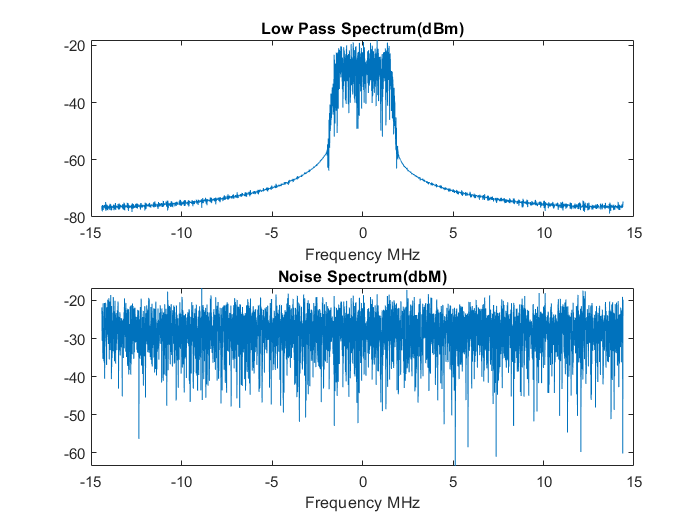

nfft = 4096;
f = ([0:nfft-1]/nfft*fs - fs/2 )/(10^6);
Yf = fftshift(fft(y, nfft))/nfft;
Xf = fftshift(fft(x, nfft))/nfft;
R = 50;
P_x = 10 * log10((abs(Xf).^2)/(2*R)) + 30;
P_y = 10 * log10((abs(Yf).^2)/(2*R)) + 30;
subplot(2,1,1)
plot(f, P_y)
xlabel("Frequency MHz")
title("Low Pass Spectrum(dBm)")
subplot(2,1,2)
plot(f , P_x)
xlabel("Frequency MHz")
title("Noise Spectrum(dbM)")

## Part B

nfft = 4096

nfft = 4096

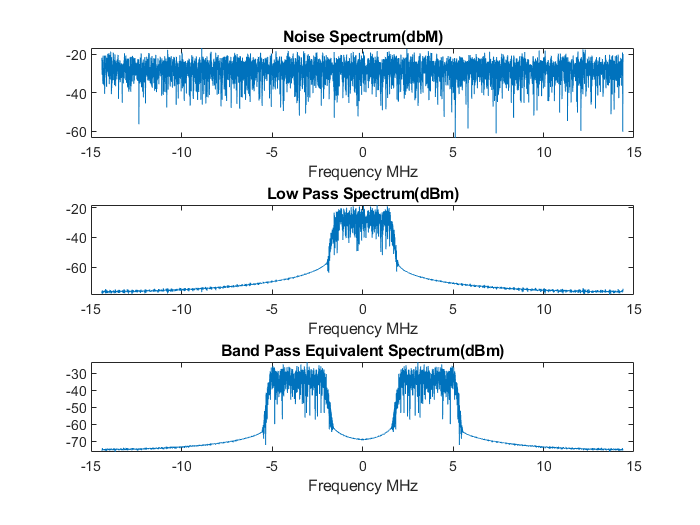

n = 1:nfft;
fc = 3.57 * 10^6;
y_bandpass = real(y .* exp(1i * 2* pi* fc * n/fs));
Y_bandpassf = fftshift(fft(y_bandpass, nfft))/nfft;
P_ybandpass = 10 * log10((abs(Y_bandpassf).^2)/(2*R)) + 30;
subplot(3,1,2)
plot(f, P_y)
xlabel("Frequency MHz")
title("Low Pass Spectrum(dBm)")
subplot(3,1,1)
plot(f , P_x)
xlabel("Frequency MHz")
title("Noise Spectrum(dbM)")
subplot(3,1,3)
plot(f, P_ybandpass)
xlabel("Frequency MHz")
title("Band Pass Equivalent Spectrum(dBm)")
hold off


yb_power = y_bandpass*transpose(conj(y_bandpass))/(length(y_bandpass));
fprintf("Noise Power: %4.3f", x_power);

Noise Power: 1.012

fprintf("Base Band Power: %4.4f", y_power);

Base Band Power: 0.1139

fprintf("Band Pass Power: %4.4f", yb_power);

Band Pass Power: 0.0570

fprintf("As we can see the power of bandpass equivalent of low pass signal " + ...
    "has been changed.\n Since in Band Pass equivalent we only get the real part of signal" + ...
    " and some part of it has been ignored.")

As we can see the power of bandpass equivalent of low pass signal has been changed.
 Since in Band Pass equivalent we only get the real part of signal and some part of it has been ignored.

## Part C

fc1 = 0.7 * 10^6;
fc2 = 1.4 * 10^6;
fc3 = 2.8 * 10^6;

n = (1:nfft)/fs;
y_i = y_bandpass .* (2*cos(2*pi*fc*n));
y_q = y_bandpass .* (-2*sin(2*pi*fc*n));
y = y_i + 1i.*y_q;


b_filt_0p7 = fir1(120, fc1*2/fs, "low");
b_filt_1p4 = fir1(120, fc2*2/fs, "low");
b_filt_2p8 = fir1(120, fc3*2/fs, "low");

y_l_0p7 = filter(b_filt_0p7, 1, y)

y_l_0p7 =    0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0001i  -0.0000 - 0.0001i  -0.0000 - 0.0002i  -0.0000 - 0.0003i  -0.0001 - 0.0005i  -0.0002 - 0.0006i  -0.0002 - 0.0008i  -0.0003 - 0.0010i  -0.0004 - 0.0012i  -0.0005 - 0.0014i  -0.0007 - 0.0016i  -0.0009 - 0.0018i  -0.0011 - 0.0020i  -0.0014 - 0.0022i  -0.0017 - 0.0023i  -0.0020 - 0.0023i  -0.0023 - 0.0023i  -0.0027 - 0.0022i  -0.0031 - 0.0019i  -0.0035 - 0.0014i  -0.0038 - 0.0009i  -0.0041 - 0.0002i  -0.0043 + 0.0006i  -0.0044 + 0.0017i  -0.0044 + 0.0028i  -0.0042 + 0.0041i  -0.0038 + 0.0056i  -0.0033 + 0.0071i  -0.0024 + 0.0087i  -0.0013 + 0.0102i   0.0000 + 0.0118i   0.0017 + 0.0132i   0.0036 + 0.0144i   0.0058 + 0.0154i   0.0082 + 0.0161i   0.0108 + 0.0164i   0.0136 + 0.0162i   0.0164 + 0.0154i   0.0193 + 0.0140i   0.0220 + 0.0120i   0.0245 + 0.0092i   0.0267 + 0.0056i   0.0284 + 0.0013i   0.0295 - 0.0039i   0.0298 - 0.0099i   0.0292 - 0.0166i   0.0276 - 0.0240i   0.0248 - 0.0321i


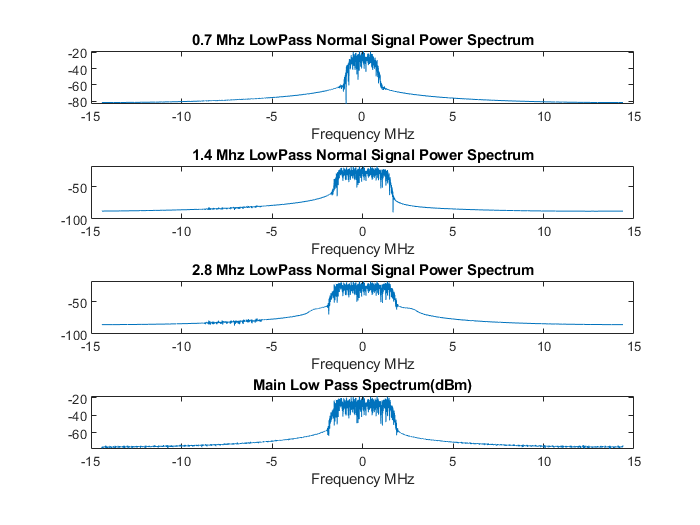

fy_0p7 = fftshift(fft(y_l_0p7, nfft))/nfft;
P_y_0p7 = 10 * log10((abs(fy_0p7).^2)/(2*R)) + 30;
figure;
subplot(4,1,1)
plot(f, P_y_0p7)
title("0.7 Mhz LowPass Normal Signal Power Spectrum")
xlabel("Frequency MHz")


y_l_1p4 = conv(y, b_filt_1p4, "same");
fy_1p4 = fftshift(fft(y_l_1p4, nfft))/nfft;
P_y_1p4 = 10 * log10((abs(fy_1p4).^2)/(2*R)) + 30;
subplot(4,1,2)
plot(f, P_y_1p4)
title("1.4 Mhz LowPass Normal Signal Power Spectrum")
xlabel("Frequency MHz")

y_l_2p8 = conv(y, b_filt_2p8, "same");
fy_2p8 = fftshift(fft(y_l_2p8, nfft))/nfft;
P_y_2p8 = 10 * log10((abs(fy_2p8).^2)/(2*R)) + 30;
subplot(4,1,3)
plot(f, P_y_2p8)
xlabel("Frequency MHz")
title("2.8 Mhz LowPass Normal Signal Power Spectrum")


subplot(4,1,4)
plot(f, P_y)
xlabel("Frequency MHz")
title("Main Low Pass Spectrum(dBm)")

sig_power = @(x) x*transpose(conj(x));

fprintf("Power of 0.7MHz filtered signal is: %1.4f",sig_power(fy_0p7))

Power of 0.7MHz filtered signal is: 0.0453

fprintf("Power of 1.4MHz filtered signal is: %1.4f",sig_power(fy_1p4))

Power of 1.4MHz filtered signal is: 0.0954

fprintf("Power of 2.8MHz filtered signal is: %1.4f",sig_power(fy_2p8))

Power of 2.8MHz filtered signal is: 0.1141

fprintf("Power of original ssignal is: %1.4f",y_power)

Power of original ssignal is: 0.1139

We know that if signal be WSS the power spectral density of output given an input *x(t)* and transfer function *h(t):*

*Y(f) =*$X\left(f\right){|H\left(f\right)|}^2$  

 as the bandwidth of filter increases it lets more frequency components to contribute to total aggregate power of output, therefore the Power increases.